# Nuclei Display

This script loads the imported trace (table VL) and generates the nuclei figures used in the manuscript

**Additional Requirements:**

- the MatGeom Library: [https://github.com/mattools/matGeom](https://github.com/mattools/matGeom) 

## Set up

clc
clearvars
setupMatGeom

Installing MatGeom Library
Adding module: geom2d               (ok)
Adding module: polygons2d           (ok)
Adding module: graphs               (ok)
Adding module: polynomialCurves2d   (ok)
Adding module: geom3d               (ok)
Adding module: meshes3d             (ok)
Adding module: utils                (ok)


### Load data

Nuclei vertices are stored in a MATLAB table variable, VL.

- **Object**: name of trace from reconstruct file

- **contour_id**: Unique identifier of trace

- **x, y, z: **x, y, and z vertices of traces from reconstruct

- **ObjId: **Id from recontruct

- **ObjType**: Type of Cell (I, II, III, etc)

load(fullfile(paths.nuclei,"nuclei_data.mat"),"VL") % load VL 

VL = 860880×7 table
             Object              contour_id      x         y         z      ObjId    ObjType
    _________________________    __________    ______    ______    _____    _____    _______

    "TB2_tastebud_outline_cw"        1         74.824    49.823    10.08     84         1   
    "TB2_tastebud_outline_cw"        1         74.868    49.644    10.08     84         1   
    "TB2_tastebud_outline_cw"        1         75.003    49.465    10.08     84         1   
    "TB2_tastebud_outline_cw"        1          75.36    49.331    10.08     84         1   
    "TB2_tastebud_outline_cw"        1         75.718    49.465    10.08     84         1   
    "TB2_tastebud_outline_cw"        1         75.987    49.823    10.08     84         1 

pp = VL.Properties.UserData.patchProps

pp = 8×5 table
    numType     cellType               faceColor              faceAlpha    alphaRadius
    _______    __________    _____________________________    _________    ___________

       1       "tastebud"          0          0          0      0.01            6     
       2       "I"                 0          1          0      0.25            5     
       3       "II"                0          0          1      0.25            5     
       4       "II/III"          0.5        0.5        0.5       0.5            5     
       5       "III"               1          0          0      0.25            5     
       6       "IId"          0.7059     0.6078     0.8023      0.25            5     
       7       "IV"          0.91373    0.59216    0.97255      0.35            5     
       8       "x"            0

### Analysis

Analyze nuclei

T = getNucleiMetrics(VL);
t = T(T.CellType ~="tastebud",:);

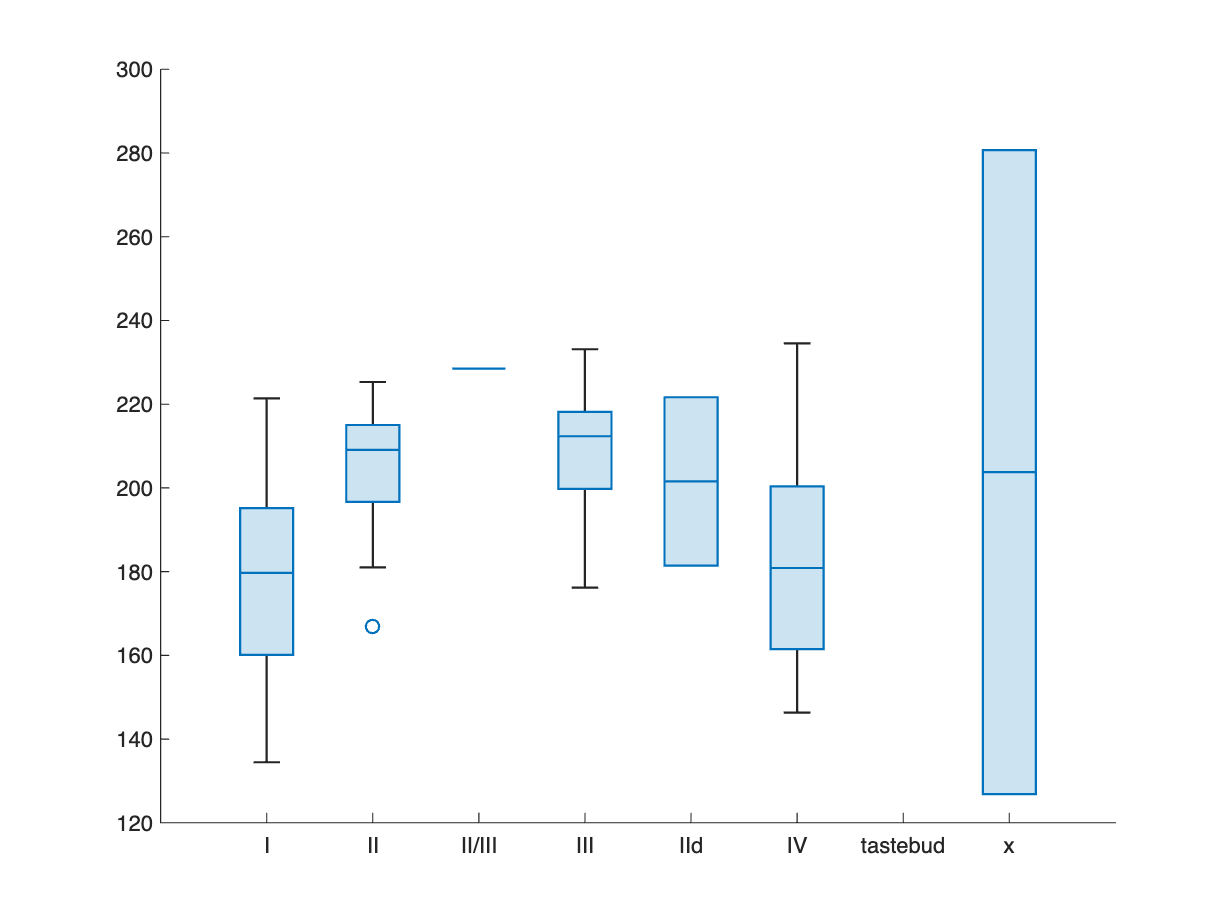

figure
boxchart(t.CellType,t.Volume)

### Estimate radius from volume


$$r=\left(3V/4\pi \right)$$


g = groupsummary(T,"CellType","mean","Volume")
g.Radius = (g.mean_Volume * 3)./(4*pi)

### Display Bud and Nuclei

#### color by cell type

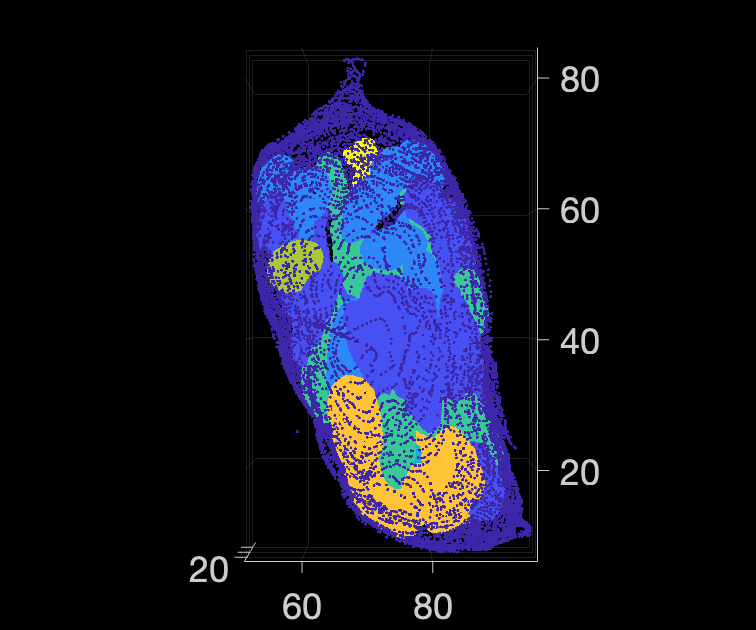

figure
PC = pointCloud(VL{:,["x" "y" "z"]});
pcshow(PC.Location, VL.ObjType,ViewPlane="XY")

#### Recenter Bulb

- change color map to manuscript colors

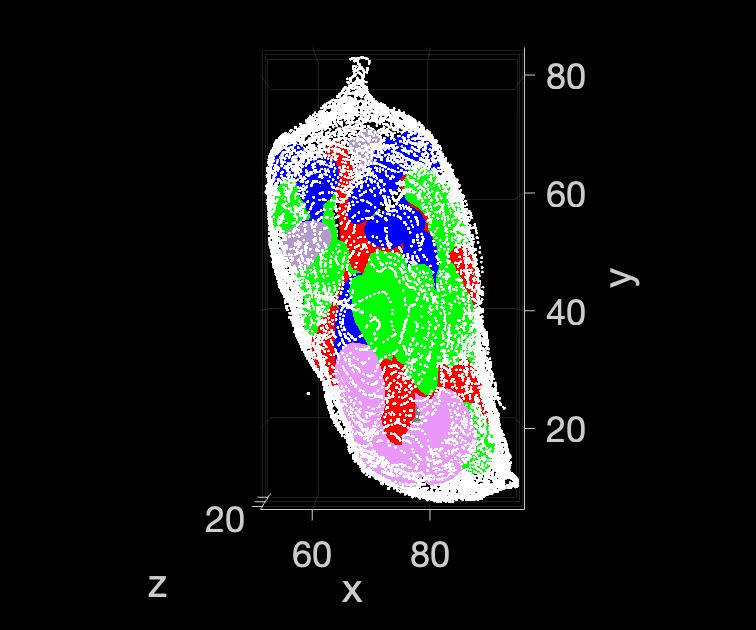

set(gca,CameraTarget=mean(PC.Location)) % center of tastebud
cm = VL.Properties.UserData.patchProps.faceColor;
cm(1,:) = ones(1,3);
colormap(cm)

xlabel('x'), ylabel('y'), zlabel('z')
axis on

### Straighten bud

run previous block first

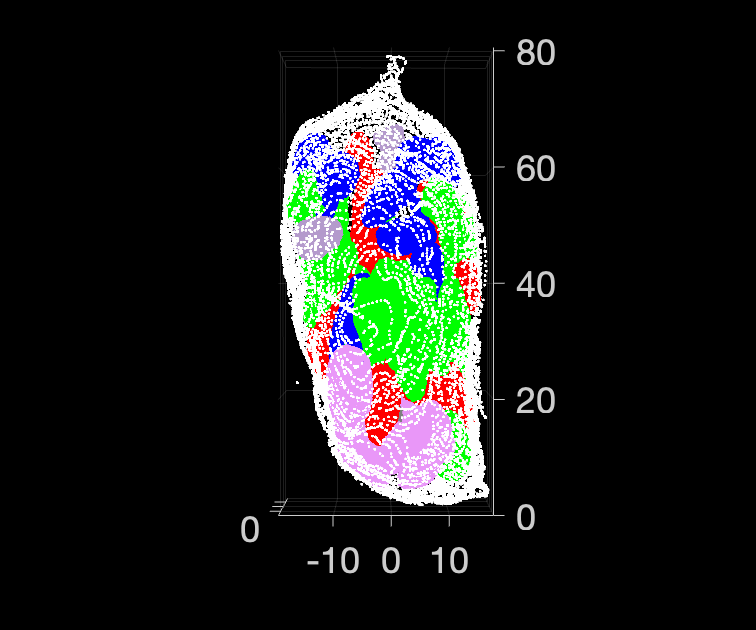

PC = straighten_bud(VL, 78); % second input should indicate pore location on y-axis
pcshow(PC.Location,VL.ObjType,ViewPlane="XY")
set(gca,CameraTarget=mean(PC.Location))

ax_view = get(gca,"View")

ax_view =      0    90


### Patch Property Updates (as needed)

Patch properties used to set display properties such as faceColor and faceAlpha. alphaRadius is used for the shapeAlpha function

pp = VL.Properties.UserData.patchProps

pp = 8×5 table
    numType     cellType               faceColor              faceAlpha    alphaRadius
    _______    __________    _____________________________    _________    ___________

       1       "tastebud"          0          0          0      0.01            6     
       2       "I"                 0          1          0      0.25            5     
       3       "II"                0          0          1      0.25            5     
       4       "II/III"          0.5        0.5        0.5       0.5            5     
       5       "III"               1          0          0      0.25            5     
       6       "IId"          0.7059     0.6078     0.8023      0.25            5     
       7       "IV"          0.91373    0.59216    0.97255      0.35            5     
       8       "x"            0

**Purple values**

- for type IV cells: R 233, G 151, B 248

- for dying cells: R 226, G 209, B 255

([233 151 248])/255

ans =       0.91373      0.59216      0.97255


mat2gray([226 209 255])

ans =       0.36957            0            1


### Property adjustment as needed

% pp.faceColor(1,:) = zeros(1,3);
% pp.faceAlpha(2:end) = 0.25;
% pp.alphaRadius(2:end) = 5;

pp.faceColor(7,:) = ([233 151 248])/255;
pp.faceAlpha(7) = 0.35;
pp.faceColor(4,:) = repmat(0.5, 1,3);
pp.faceAlpha(4) = 0.5

pp = 8×5 table
    numType     cellType               faceColor              faceAlpha    alphaRadius
    _______    __________    _____________________________    _________    ___________

       1       "tastebud"          0          0          0      0.01            6     
       2       "I"                 0          1          0      0.25            5     
       3       "II"                0          0          1      0.25            5     
       4       "II/III"          0.5        0.5        0.5       0.5            5     
       5       "III"               1          0          0      0.25            5     
       6       "IId"          0.7059     0.6078     0.8023      0.25            5     
       7       "IV"          0.91373    0.59216    0.97255      0.35            5     
       8       "x"            0

VL.Properties.UserData.patchProps = pp; % update properties in table

#### Save table with updated patch properties

save(VL.Properties.UserData.file,"VL")

## Plot AlphaShapes

### Plot One Panel

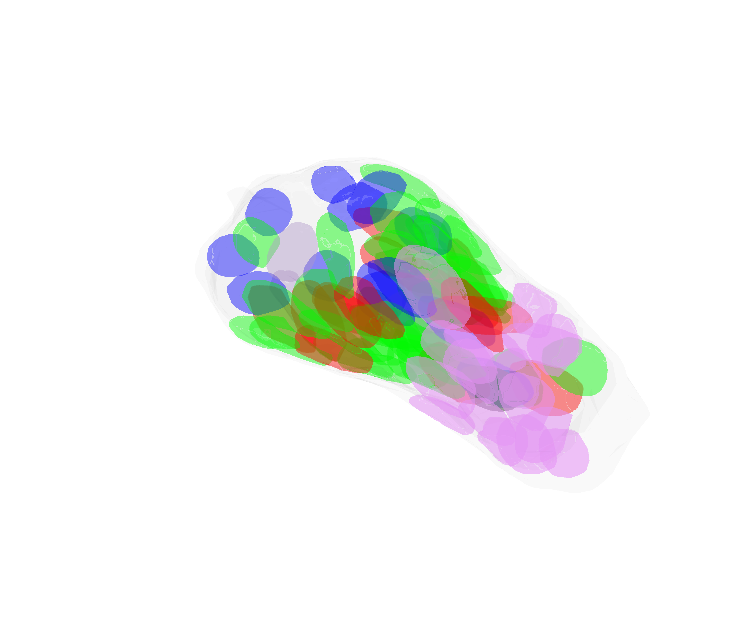

figure
hp = plot_all_surface(PC,VL,true);

### Plot in Separate panels

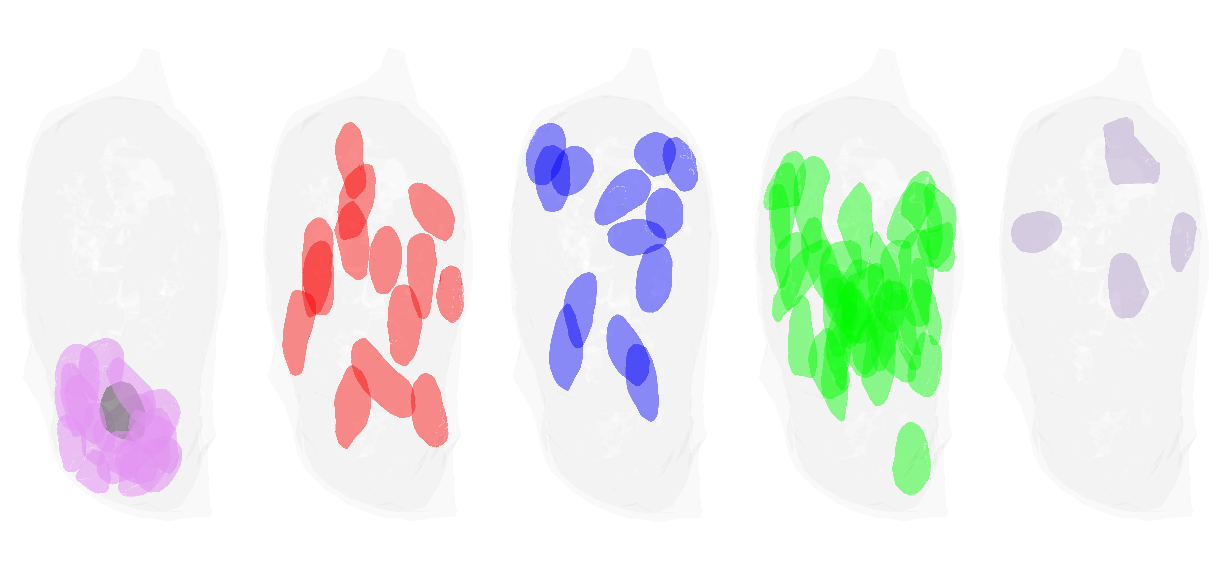

figure(Visible="on")
tiledlayout("horizontal",TileSpacing="none",Padding="tight")
VL.Properties.UserData.patchProps = pp;

typeIndc = {[1 4 7], [1 5],[1 3],[1 2], [1 6 8]};

count = numel(typeIndc);
ax = gobjects(count,1);
for n=1:count
    ax(n) =  nexttile;
    for r=typeIndc{n}
        la = ismember(VL.ObjType,r);

        plot_all_surface(select(PC,la),VL(la,:),true);
        
    end
end
hlink = linkprop(ax,{'CameraPosition','CameraUpVector','CameraViewAngle'});
set(ax, CameraViewAngle=5,View=[10 90])

### Export figure

Longitudinal view

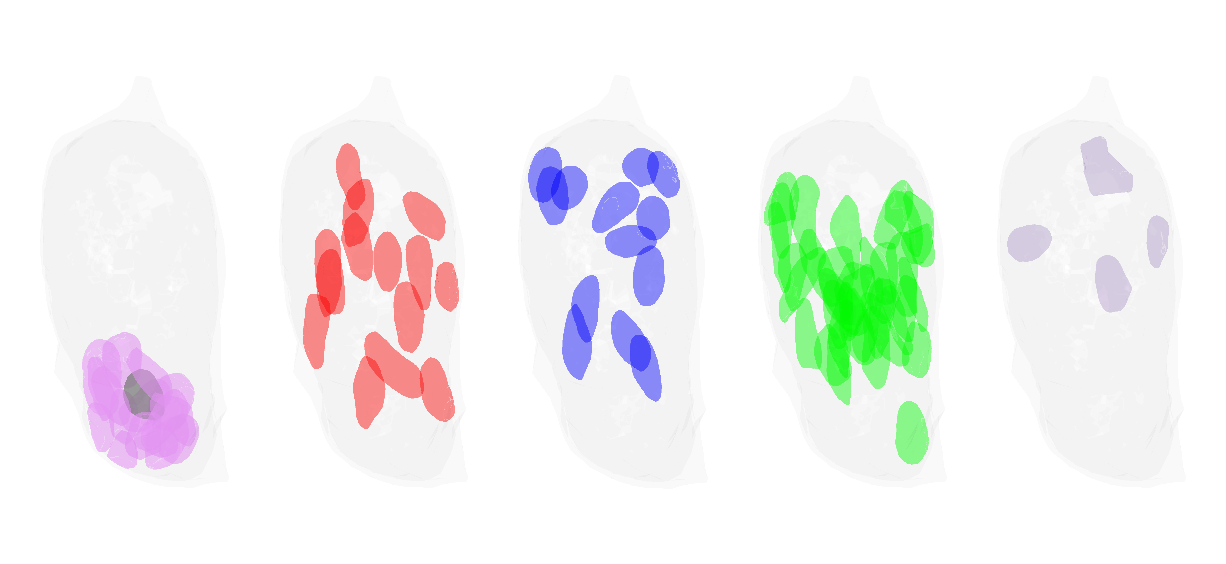

view([10 90])
exportgraphics(gcf,fullfile(path.project,"Figures","nuclei-longitudinal.png"),Resolution=600)

Transverse view

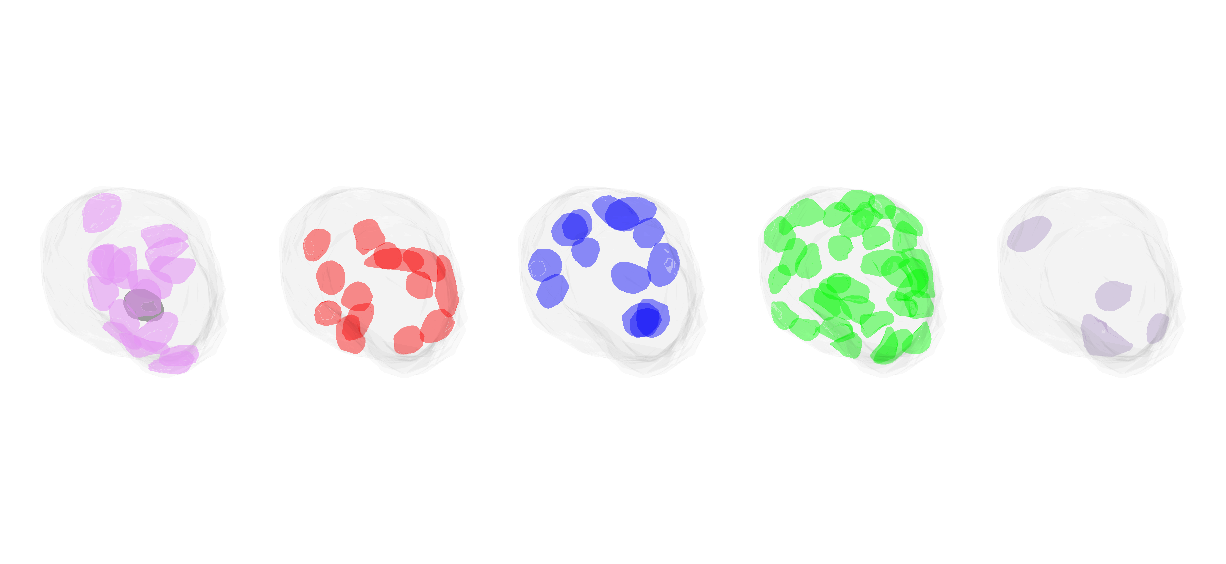

view([0 0])
exportgraphics(gcf,fullfile(path.project,"Figures","nuclei-transverse.png"),Resolution=600) 

# Local Functions

## plot as surfaces

function hp = plot_all_surface(PC,VL,fast_plot)
% plots taste bud and nuclei using alphaShape

arguments
    PC pointCloud
    VL table
    fast_plot logical = true;
end

pp = VL.Properties.UserData.patchProps;

objects = unique(VL.Object);
count = numel(objects);
hp = gobjects(count,1);
for n=1:count
    la = VL.Object==objects(n);
    vl = VL(la,:);
    pc = select(PC,la);
    % shp = alphaShape(vl{:,["x","y","z"]});

    r = mode(vl.ObjType); % row corresponding to type

    if fast_plot
        hp(n) = plot_alphaShape(pc,vl.Object(1),pp(r,:));
    else
        hp(n) = plot_patch(pc.Location, vl.Object(1),pp(r,:));
    end

    hold on

end
axis off
lighting gouraud
% material shiny
% set(gcf,'Color','k')
% view([0 90])
end


### plot_alphaShape

function hp = plot_alphaShape(pc,tag,ppr)

ar = ppr.alphaRadius;

% k = boundary(pc.Location,0); % get convex hull
% shp = alphaShape(k,ar);
shp = alphaShape(pc.Location,ar);

% color = pp.faceColor(unique(vl.ObjType),:);
hp = plot(shp, ...
    FaceColor=ppr.faceColor, ...
    FaceAlpha=ppr.faceAlpha, ...
    EdgeColor='none', ...
    Tag=tag);
end


### plot_patch

create surface mesh from point clouds and plot. Called here

function hp = plot_patch(verts,tag,ppr)

arguments
    verts (:,3) double
    tag char
    ppr (1,:) table 
end

PC = pointCloud(verts);
% SM = pc2surfacemesh(PC,"ball-pivot",[50,50,70]);
[sm, ~] = pc2surfacemesh(PC,"ball-pivot");
removeDefects(sm,"nonmanifold-edges")
removeDefects(sm,"degenerate-faces")
removeDefects(sm,"unreferenced-vertices")
removeDefects(sm,"duplicate-vertices")
removeDefects(sm,"duplicate-faces")

hp = patch(Faces=sm.Faces, ...
    Vertices=sm.Vertices, ...
    FaceColor=ppr.faceColor, ...
    FaceAlpha=ppr.faceAlpha, ...
    EdgeColor='none', ...
    BackFaceLighting='unlit',...
    Tag=tag);
end

##  straighten_bud 

function PC = straighten_bud(VL, pore_cutoff)

% create point cloud
PC = pointCloud(VL{:,["x" "y" "z"]});

% capture axis
% y_cutoff = 78; % make sure this matches the y-range seen in the figure above
pbAX.la = PC.Location(:,2) > pore_cutoff & PC.Location(:,2) <= max(PC.Location(:,2)); % select pore vertices 9700
pbAX = get_pore_bud_axis(pbAX, PC);

% recenter
tform = rigidtform3d([0 0 0],-mean(pbAX.PCbud.Location)); % center main bud at 0,0,0
PC = pctransform(PC,tform);
pbAX = get_pore_bud_axis(pbAX, PC);

% transform
tform = rigidtform3d([0 0 pbAX.anglz],[0 0 0]); % rotate around z-axis
PC = pctransform(PC,tform);

tform = rigidtform3d([-pbAX.anglx 0 0],[0 0 0]); % rotate around x-axis
PC = pctransform(PC,tform);

tform = rigidtform3d([0 0 0],[0 -min(PC.Location(:,2)) 0]); % move min Y to 0
PC = pctransform(PC,tform);
% pbAX = get_pore_bud_axis(pbAX, PC);
end


## get_pore_bud_axis 

function pbAX = get_pore_bud_axis(pbAX, PC)
pbAX.PCpore = select(PC,pbAX.la);
pbAX.PCbud = select(PC,~pbAX.la);
pbAX.C = zeros(2,3);
pbAX.C(1,:) = mean(pbAX.PCbud.Location); % centroid pore
pbAX.C(2,:) = mean(pbAX.PCpore.Location); % centroid bud
pbAX.sides = diff(pbAX.C); % lengths of triangle
pbAX.oaxy = pbAX.sides(1)/pbAX.sides(2); % opposite / adjacent
pbAX.anglz = atand(pbAX.oaxy); % angle around z axis

pbAX.oazy = pbAX.sides(3)/pbAX.sides(2);
pbAX.anglx = atand(pbAX.oazy); % angle around x axis
end


function T = getNucleiMetrics(VL)

pp = VL.Properties.UserData.patchProps;
PC = pointCloud(VL{:,["x" "y" "z"]});

objects = unique(VL.Object);
count = numel(objects);

T = table(zeros(count, 1), strings(count,1), zeros(count, 1),...
    VariableNames = {'NumType','CellType','Volume'});

for n=1:count
    la = VL.Object==objects(n);
    vl = VL(la,:);
    pc = select(PC,la);
    % shp = alphaShape(vl{:,["x","y","z"]});

    r = mode(vl.ObjType); % row corresponding to type

    ar = pp.alphaRadius(r);
    shp = alphaShape(pc.Location,ar);

    T.NumType(n) = r;
    T.CellType(n) = pp.cellType(r);
    T.Volume(n) = shp.volume;
end
T.CellType = categorical(T.CellType);
end